# Live Script PageRank - mathwork200.mat

load mathwork200.mat;

Di seguito si utilizza la funzione pagerank tramite il function file pagerank.mlx. Con i risultati forniti dalla funzione, vengono generati i grafici richiesti:  un grafico che visualizza la struttura di G, il grafo associato, i primi 15 risultati in ordine decrescente, con i corrispondenti outdegree e indegree, un grafico a barre del PageRank ed il sottografo costituito dai nodi con rank maggiore della media dei rank. 

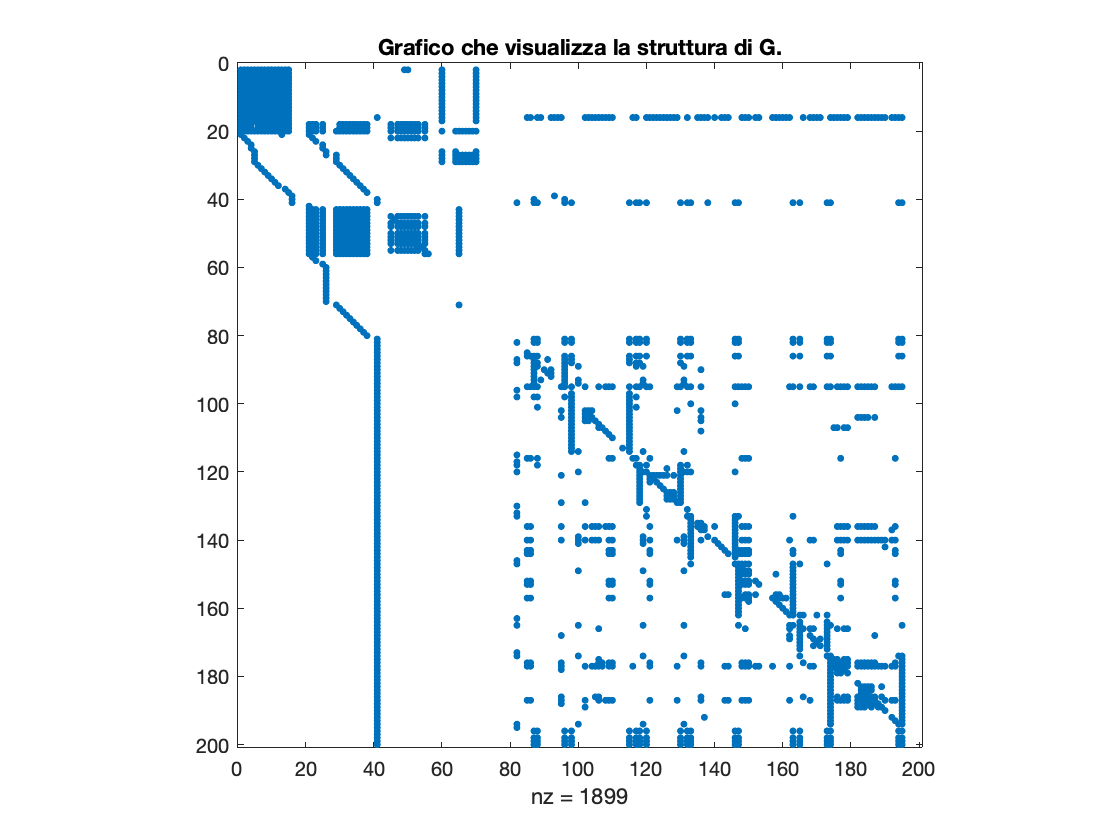

figure(1);
spy(G);
title('Grafico che visualizza la struttura di G.');

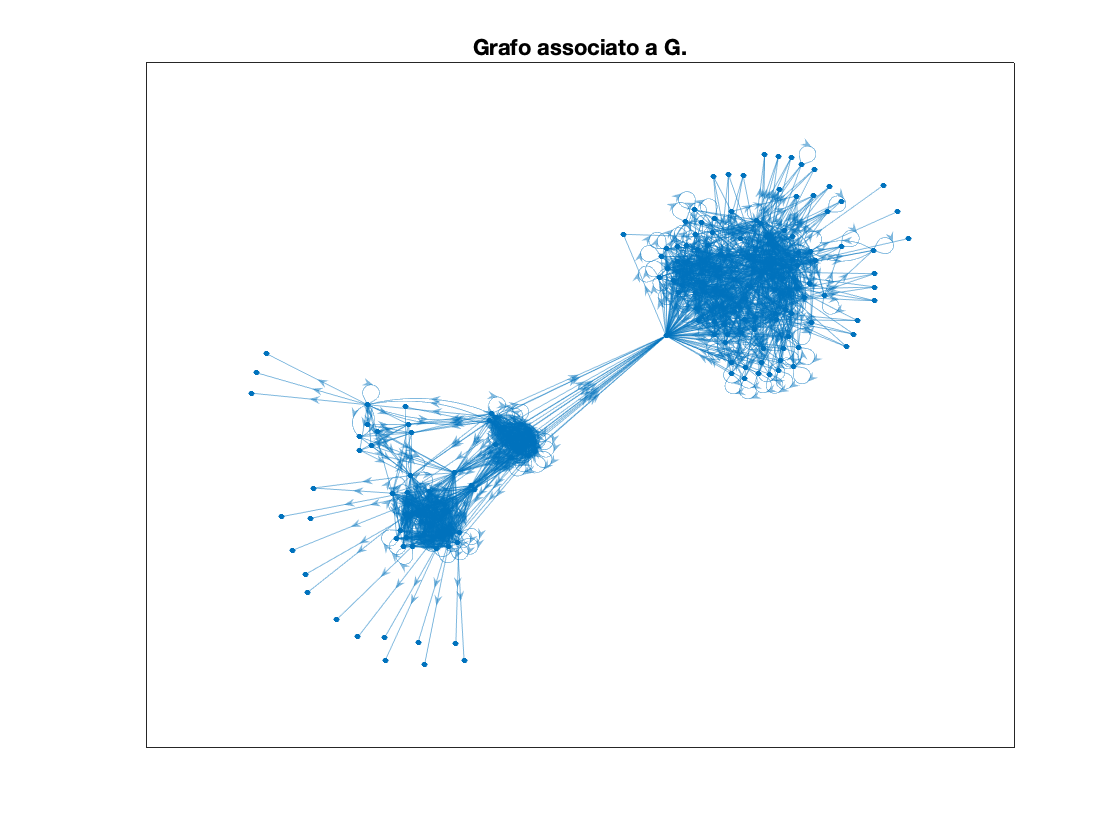

figure(2);
gs = digraph(G', 'omitselfloops');
p = plot(gs);
layout(p,'force');
title('Grafo associato a G.');

[R, outdegree, indegree] = pagerank(G);
indegree

indegree =    (2,1)       18
   (3,1)       16
   (4,1)       16
   (5,1)       16
   (6,1)       16
   (7,1)       16
   (8,1)       16
   (9,1)       16
  (10,1)       16
  (11,1)       16
  (12,1)       16
  (13,1)       16
  (14,1)       16
  (15,1)       16
  (16,1)       91
  (17,1)       17
  (18,1)       36
  (19,1)       36
  (20,1)       46
  (21,1)        2
  (22,1)       10
  (23,1)        1
  (24,1)        2
  (25,1)        1
  (26,1)        4
  (27,1)       11
  (28,1)       10
  (29,1)        9
  (30,1)        1
  (31,1)        1
  (32,1)        1
  (33,1)        1
  (34,1)        1
  (35,1)        1
  (36,1)        1
  (37,1)        1
  (38,1)        1
  (39,1)        2
  (40,1)        4
  (41,1)       22
  (42,1)        1
  (43,1)       15
  (44,1)       15
  (45,1)       23
  (46,1)       15
  (47,1)       23
  (48,1)       23
  (49,1)       15
  (50,1)       23
  (51,1)       23
  (52,1)       23
  (53,1)       23
  (54,1)       16
  (55,1)       23
  (56,1)       16

outdegree

outdegree =    (1,1)       20
   (1,2)       19
   (1,3)       19
   (1,4)       20
   (1,5)       20
   (1,6)       19
   (1,7)       19
   (1,8)       19
   (1,9)       19
   (1,10)      19
   (1,11)      19
   (1,12)      19
   (1,13)      19
   (1,14)      19
   (1,15)      19
   (1,16)       3
   (1,21)      18
   (1,22)      18
   (1,23)      18
   (1,25)      19
   (1,26)      12
   (1,29)      18
   (1,30)      18
   (1,31)      18
   (1,32)      18
   (1,33)      18
   (1,34)      18
   (1,35)      18
   (1,36)      18
   (1,37)      18
   (1,38)      18
   (1,41)     122
   (1,45)      11
   (1,47)      11
   (1,48)      11
   (1,49)      13
   (1,50)      12
   (1,51)      11
   (1,52)      11
   (1,53)      12
   (1,55)      12
   (1,60)      21
   (1,64)       5
   (1,65)      19
   (1,66)       4
   (1,67)       4
   (1,68)       4
   (1,69)       4
   (1,70)      21
   (1,82)      20
   (1,85)      14
   (1,86)      13
   (1,87)      18
   (1,88)      15
   (1,89)       

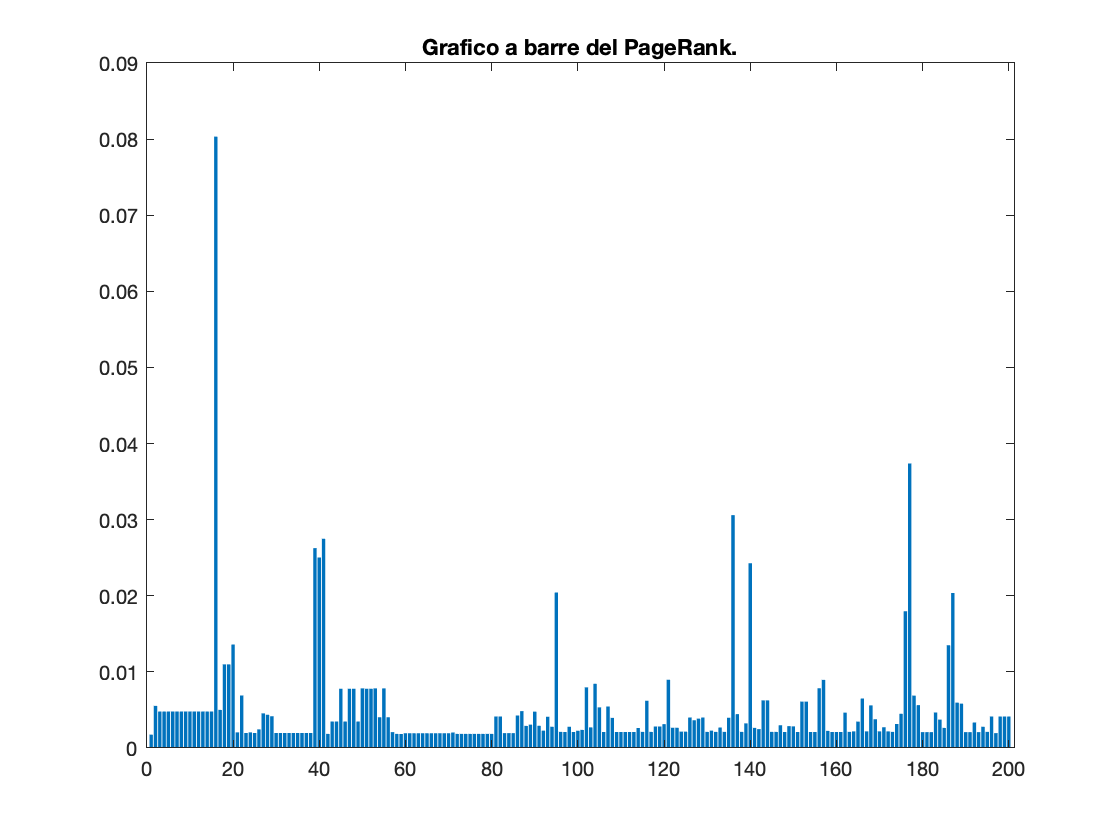

figure(3);
bar(R);
title('Grafico a barre del PageRank.');

outdegree = outdegree';
T = table(U, indegree, outdegree, R);
T = sortrows(T, 'R', 'descend');
T = head(T,15)

T = 15×4 table
                            U                                  indegree               outdegree                   R          
    _________________________________________________    ____________________    ____________________    ____________________

    'http://schema.org'                                  9.10000000000000e+01    3.00000000000000e+00    8.03187473922823e-02
    'http://schema.org/CreativeWork'                     4.30000000000000e+01    1.40000000000000e+01    3.73794993695824e-02
    'http://schema.org/Offer'                            3.10000000000000e+01    1.40000000000000e+01    3.05887665373423e-02
    'http://blog.schema.org'                             2.20000000000000e+01    1.22000000000000e+02    2.74852834350127e-02
    'http://schema.org/docs/about.html'                  2.00000000000000e+00    0.000000000

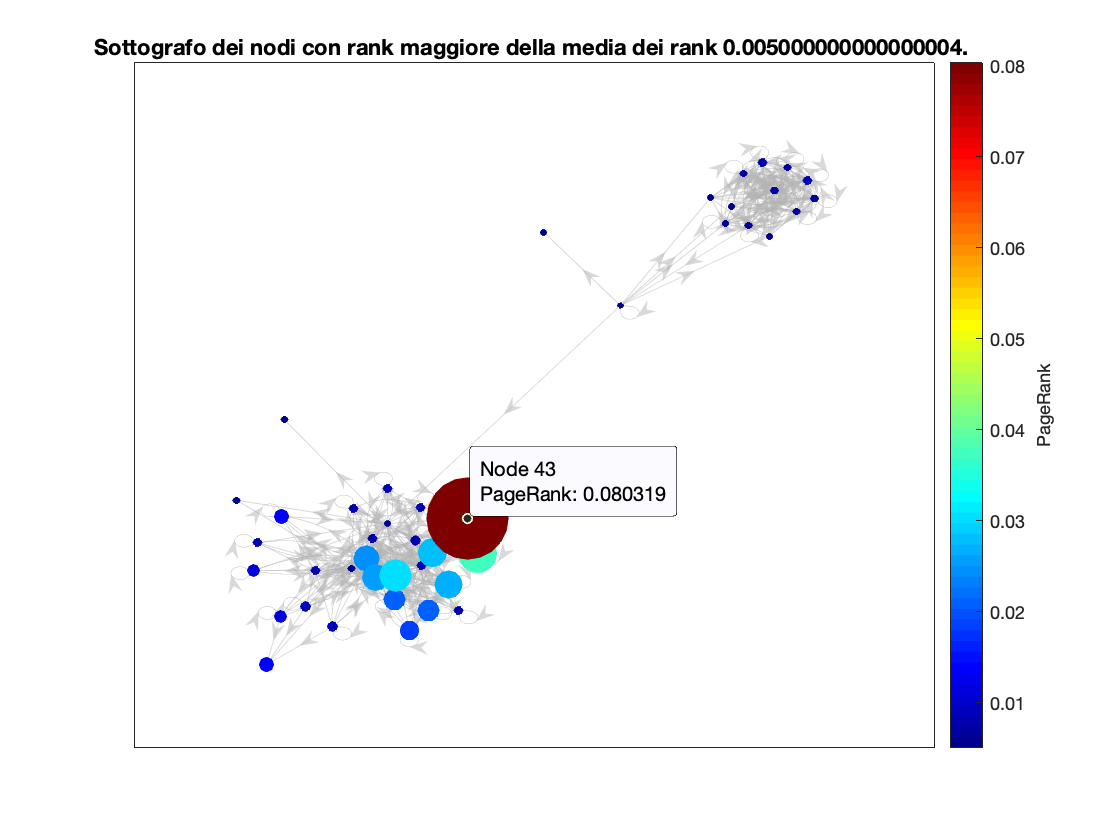

%%%% Plot del sottografo %%%%%

M = mean(R); % Calcolo media.
rank_sorted = sort(R(R>M)); % Vettore dei rank ordinati.
g_media = subgraph(gs, R>M); % Sottografo dei nodi con rank maggiori della media.


% Plot effettivo del sottografo
figure(4);
p = plot(g_media, 'NodeLabel',{},'MarkerSize',rank_sorted*500, 'NodeCData', rank_sorted, 'EdgeColor',[.7 .7 .7]);
colormap jet; % Impostazione colormap per bar laterale.
layout(p,'force'); % Disposizione nodi
ylabel(colorbar, 'PageRank'); % Aggiunta label alla bar laterale.

% Visualizzazione rank nella label del nodo (vedi funzione GraphCursorCallback.m).
g_media.Nodes.PageRank = rank_sorted; % Impostiamo la voce PageRank nella label.
hdt = datacursormode;
hdt.UpdateFcn = @(obj, event_obj) GraphCursorCallback(obj, event_obj, g_media.Nodes); % Visualizzazione Label

% Aggiunta titolo al grafico.
title(['Sottografo dei nodi con rank maggiore della media dei rank ' num2str(M,16) '. ']);